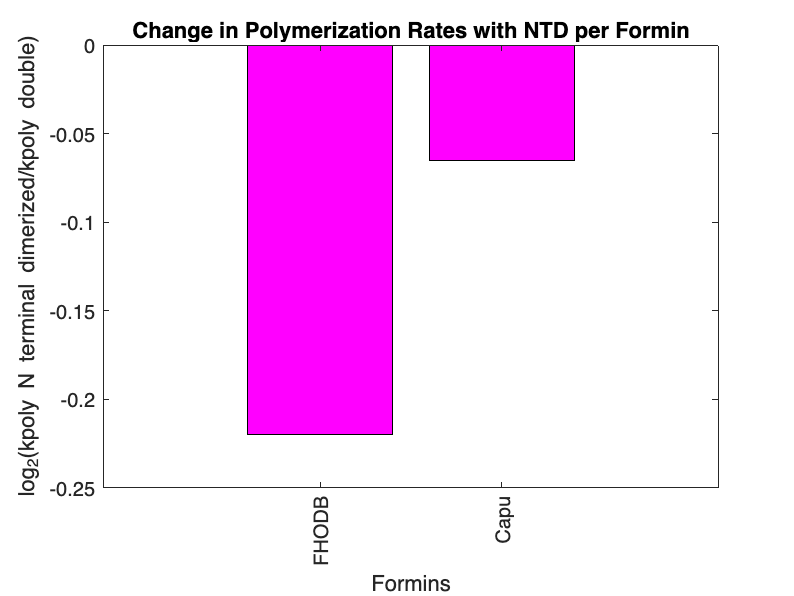

i=2;
%vals=T2{i,3:7};
%vals=T{i,2:6};
%vals=T3{i,8:12};
%vals=reasonable{i,8:12};
%vals=abs(params_FHOD);
%vals=FHOD_T{i,2:6};
vals=Capu_T{i,2:6};
%vals=Capu_T_reas{i,2:6};
vals=num2cell(vals);

x=[...
        (log2(FHOD.kdim(vals{:})./(FHOD.kdob(vals{:})))),...
        (log2(Capu.kdim(vals{:})./(Capu.kdob(vals{:}))))...
    ];
y={FHOD.name; Capu.name};
kpoly_table_ratio = table(x', 'RowNames', y);
kpoly_bar_ratio = bar(kpoly_table_ratio{:,:});
set(gca,'xtick',1:2, 'xticklabel',kpoly_table_ratio.Properties.RowNames)
xtickangle(90)
set(kpoly_bar_ratio(1), 'FaceColor','m')
xlabel('Formins')
ylabel('log_2(kpoly N terminal dimerized/kpoly double)')
%ylim([-0.62 0.3])
%ylim([-0.05 0.1])


title('Change in Polymerization Rates with NTD per Formin')

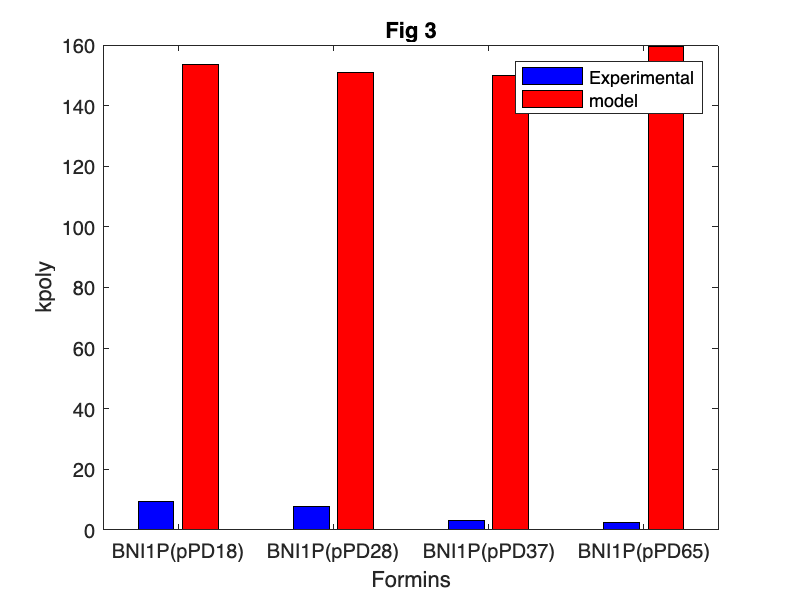

kpolybar=bar([fig3k',fig3ksimf(vals{:})]);
set(gca,'xticklabel',{fig3sim.name});

    set(kpolybar(1), 'FaceColor','b');
    set(kpolybar(2), 'FaceColor','r');
    legend( 'Experimental', 'model');
    xlabel('Formins');
    ylabel('kpoly');
    title("Fig 3")

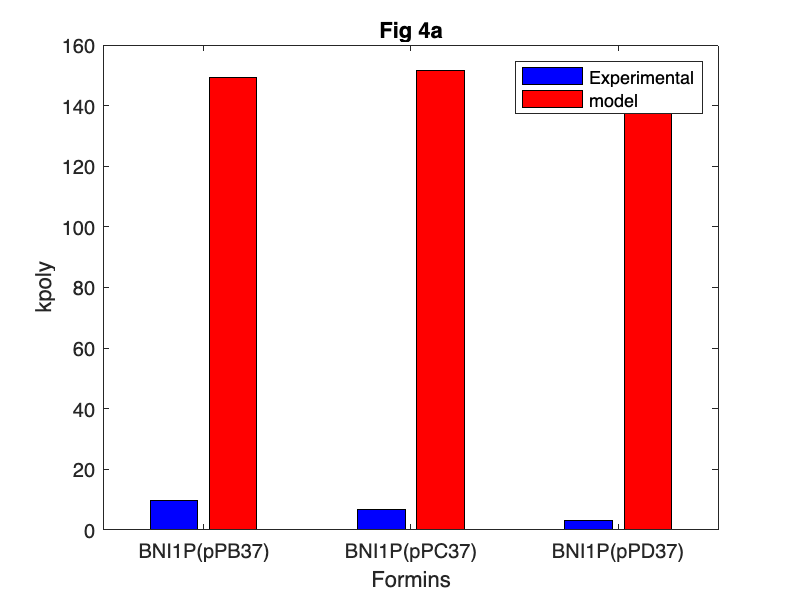


kpolybar=bar([fig4ak',fig4aksimf(vals{:})]);
set(gca,'xticklabel',{fig4asim.name});

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4a")